% Parameters
points_per_mm       =                           .1;
tube_dia            =                        17.08;
Coil_Radious        =                          250;                         % Radius of the slinky coil
Revolution          =                           12;                         % Number of turns
length              =                         3230;
dept           = 500;
dept_bend_radious = 200;


        % Compute the slinky coil
        slinky_coil = slinky(points_per_mm, tube_dia, Coil_Radious, Revolution, length);

        % Compute the turn tube and bends
        [turn_tube, bend] = turntube(points_per_mm, tube_dia, Coil_Radious, slinky_coil);
        [inlet, bend_in, outlet, bend_out] = con_tube(dept, dept_bend_radious, turn_tube, slinky_coil, points_per_mm);

dept = 500

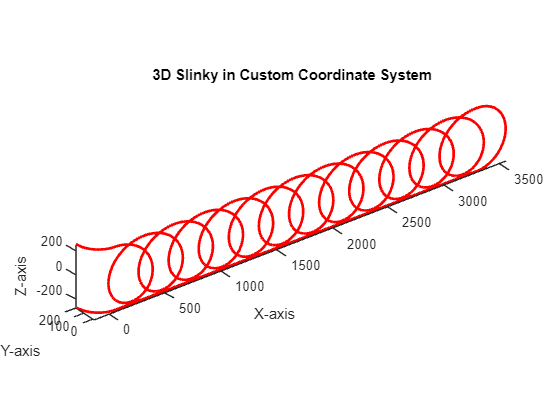


        % Combine all coordinates
        Co_ordinates = [inlet(:,1:end-1), bend_in(:,1:end-1), slinky_coil(:,1:end-1), bend(:,1:end-1), turn_tube(:,1:end-1), bend_out(:,1:end-1), outlet];
        
        figure
        % Plotting the 3D Slinky in the app's UIAxes
        plot3( Co_ordinates(1,:), Co_ordinates(2,:), Co_ordinates(3,:), 'r', 'LineWidth', 2);

        xlabel( 'X-axis');
        ylabel( 'Y-axis');
        zlabel( 'Z-axis');
        title( '3D Slinky in Custom Coordinate System');
        axis( 'equal');
        view( 3);  % Set the view to 3D

       paths = uigetdir;

paths = 'C:\Users\Simul\Documents\MATLAB\slinky_'

ans = 'C:\Users\Simul\Documents\MATLAB\slinky_\mm.txt'

file = app.file_name.value;
paths = [paths,'\',file, '.txt'];

fileID = fopen(paths, 'w');
fprintf(fileID, '%f %f %f\n', app.Co_ordinates);